# Self driving car dataset

From [Udacity](https://github.com/udacity/self-driving-car/tree/master/datasets)

License [MIT](https://github.com/udacity/self-driving-car/blob/master/datasets/LICENSE.md)

bag = rosbag('CH03_002')

bag =   BagSelection with properties:

           FilePath: 'C:\Users\ydebray\Downloads\self-driving\CH3_002\CH03_002'
          StartTime: 1.4807e+09
            EndTime: 1.4807e+09
        NumMessages: 54456557
    AvailableTopics: [36×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [54456557×4 table]


## GPS

bagGps = select(bag, 'Topic', '/vehicle/gps/fix')

bagGps =   BagSelection with properties:

           FilePath: 'C:\Users\ydebray\Downloads\self-driving\CH3_002\CH03_002'
          StartTime: 1.4807e+09
            EndTime: 1.4807e+09
        NumMessages: 13219
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [13219×4 table]


msgs = readMessages(bagGps);

msgs{1}

ans =   ROS NavSatFix message with properties:

                    MessageType: 'sensor_msgs/NavSatFix'
          COVARIANCETYPEUNKNOWN: 0
     COVARIANCETYPEAPPROXIMATED: 1
    COVARIANCETYPEDIAGONALKNOWN: 2
            COVARIANCETYPEKNOWN: 3
                         Header: [1×1 Header]
                         Status: [1×1 NavSatStatus]
                       Latitude: 37.3999
                      Longitude: -122.1081
                       Altitude: -42.5000
             PositionCovariance: [9×1 double]
         PositionCovarianceType: 0

  Use showdetails to show the contents of the message


ts = timeseries(bagGps)

  timeseries

  Common Properties:
            Name: '/vehicle/gps/fix Properties'
            Time: [13219x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [13219x9 double]
        DataInfo: 

time = ts.Time;

ts.DataInfo.UserData

ans = 9×1 cell array
    {'Header.Stamp.Sec'      }
    {'Header.Stamp.Nsec'     }
    {'Header.Seq'            }
    {'Status.Status'         }
    {'Status.Service'        }
    {'Latitude'              }
    {'Longitude'             }
    {'Altitude'              }
    {'PositionCovarianceType'}


lat = ts.Data(:,6);
lon = ts.Data(:,7);

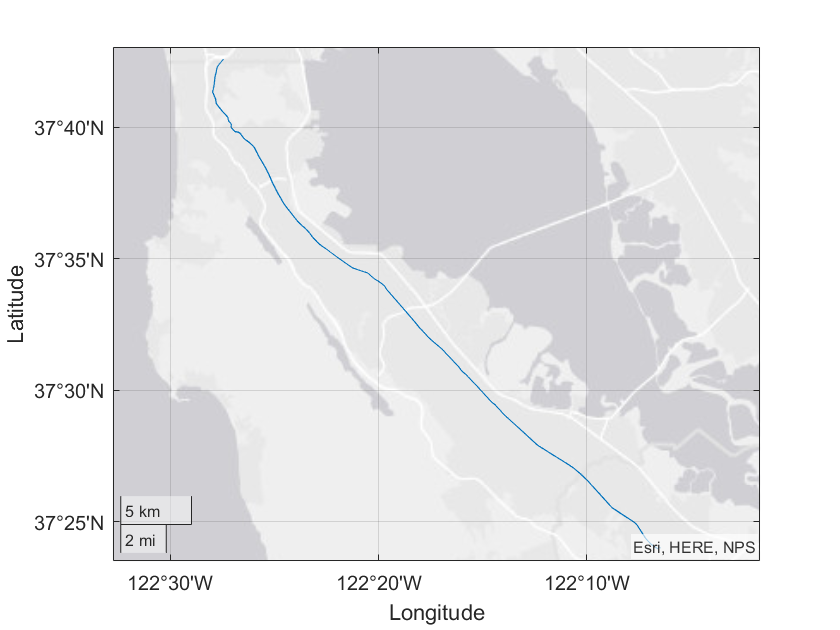

geoplot(lat,lon)

T = table(time,lat,lon)

T = 13219×3 table
       time       lat       lon  
    __________    ____    _______

    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11
    1.4807e+09    37.4    -122.11


timing = datetime(time,"ConvertFrom","epochtime","Format","HH:mm:ss") % "TimeZone","America/Los_Angeles"

timing = 13219×1 datetime array
   18:11:30
   18:11:31
   18:11:32
   18:11:33
   18:11:34
   18:11:35
   18:11:36
   18:11:37
   18:11:38
   18:11:39
   18:11:40
   18:11:41
   18:11:42
   18:11:43
   18:11:44
   18:11:45
   18:11:46
   18:11:47
   18:11:48
   18:11:49
   18:11:50
   18:11:51
   18:11:52
   18:11:53
   18:11:54
   18:11:55
   18:11:56
   18:11:57
   18:11:58
   18:11:59


TT = timetable(timing,lat,lon)

TT = 13219×2 timetable
     timing     lat       lon  
    ________    ____    _______

    18:11:30    37.4    -122.11
    18:11:31    37.4    -122.11
    18:11:32    37.4    -122.11
    18:11:33    37.4    -122.11
    18:11:34    37.4    -122.11
    18:11:35    37.4    -122.11
    18:11:36    37.4    -122.11
    18:11:37    37.4    -122.11
    18:11:38    37.4    -122.11
    18:11:39    37.4    -122.11
    18:11:40    37.4    -122.11
    18:11:41    37.4    -122.11
    18:11:42    37.4    -122.11
    18:11:43    37.4    -122.11
    18:11:44    37.4    -122.11
    18:11:45    37.4    -122.11


parquetwrite('gpsT.parquet',T)
parquetwrite('gpsTT.parquet',TT)

writetable(T,'gpsT.csv')
writetimetable(TT,'gpsTT.csv')

## Steering

bagSteering = select(bag, 'Topic', '/vehicle/steering_report')

bagSteering =   BagSelection with properties:

           FilePath: 'C:\Users\ydebray\Downloads\self-driving\CH3_002\CH03_002'
          StartTime: 1.4807e+09
            EndTime: 1.4807e+09
        NumMessages: 659858
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [659858×4 table]


bagSteering.AvailableTopics

ans = 1×3 table
                                NumMessages            MessageType                                                                                                                                                         MessageDefinition                                                                                                                                             
                                ___________    ___________________________    ___________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________

    /vehicle/steering_report    6.5986e+05     dbw_mkz_msgs/SteeringReport    {'  uint32 Seq↵  Time Stamp↵  

msgs = readMessages(bagSteering,'DataFormat','struct');

msgs{1}

ans = struct with fields:
              MessageType: 'dbw_mkz_msgs/SteeringReport'
                   Header: [1×1 struct]
       SteeringWheelAngle: -0.1379
    SteeringWheelAngleCmd: 0
      SteeringWheelTorque: 0
                    Speed: 0
                  Enabled: 0
                 Override: 0
                   Driver: 0
                 FaultWdc: 0
                FaultBus1: 0
                FaultBus2: 0
         FaultCalibration: 0
           FaultConnector: 1


steering_angle = cellfun(@(m) m.SteeringWheelAngle,msgs);
Sec = cellfun(@(m) m.Header.Stamp.Sec,msgs);
Nsec = cellfun(@(m) m.Header.Stamp.Nsec,msgs);

time = datetime(Sec,"ConvertFrom","epochtime","Format","HH:mm:ss");

% parquetwrite("steering.parquet",table(time,steering_angle))

plot(time,steering_angle)

Unrecognized function or variable 'time'.

title("Steering Wheel Angle")

## Pressure

bagpressure = select(bag, 'Topic', '/pressure')